clear
close all

# Definição do Sistema

H_s = tf(2, [1 2 1]);
time_limit = 30;
cont_step_time = 0.01;

# Análise de Malha Aberta

[y_ol, t_ol] = step(H_s, time_limit);
info = stepinfo(y_ol, t_ol)

info = struct with fields:
         RiseTime: 3.3681
    TransientTime: 5.8432
     SettlingTime: 5.8432
      SettlingMin: 1.8016
      SettlingMax: 2.0000
        Overshoot: 0
       Undershoot: 0
             Peak: 2.0000
         PeakTime: 30


# Aproximação de 1˚ Grau

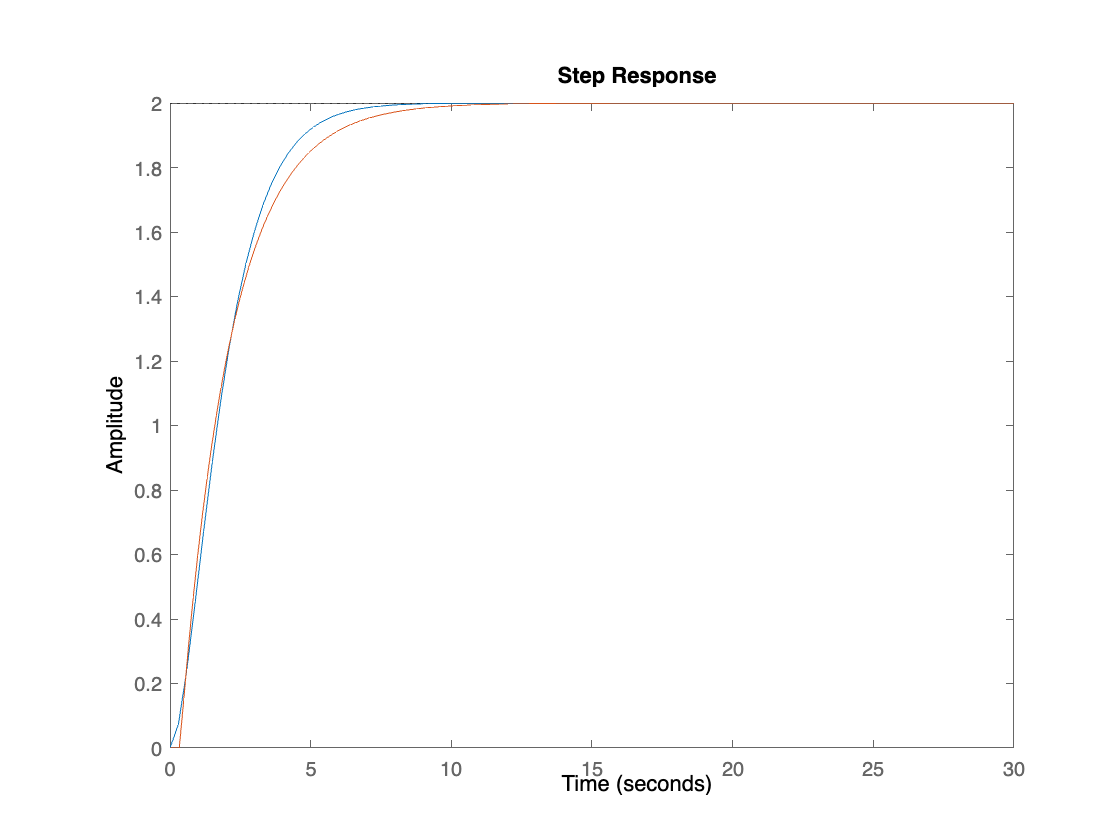

K = 2;
T = 0.35;
tau = 1.79;
M_s = tf(K, [tau 1], 'inputDelay', T);

figure(1)
step(H_s, time_limit); hold on;
step(M_s, time_limit); hold off;

# Controlador CHR

Ti = tau;
Td = T / 2;

Kp = (0.6 * tau)/(K * T)

Kp = 1.5343

Ki = Kp / Ti

Ki = 0.8571

Kd = Kp * Td

Kd = 0.2685


C_s = tf(Kd, 1) + tf(Ki, [1 0]) + tf([Kd 0], [Kd/20 1])

C_s =
 
  0.2721 s^2 + 0.28 s + 0.8571
  ----------------------------
        0.01343 s^2 + s
 
Continuous-time transfer function.



# Simulação Contínua

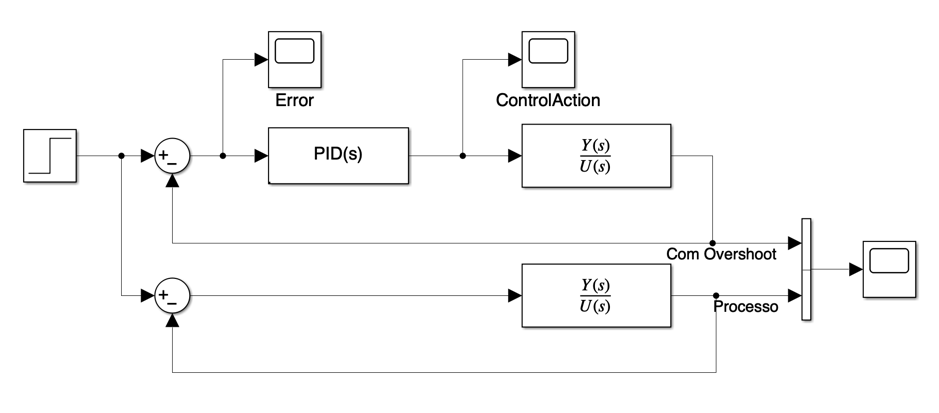

sim_cont = sim("cont.slx");

# Verificação da Simulação

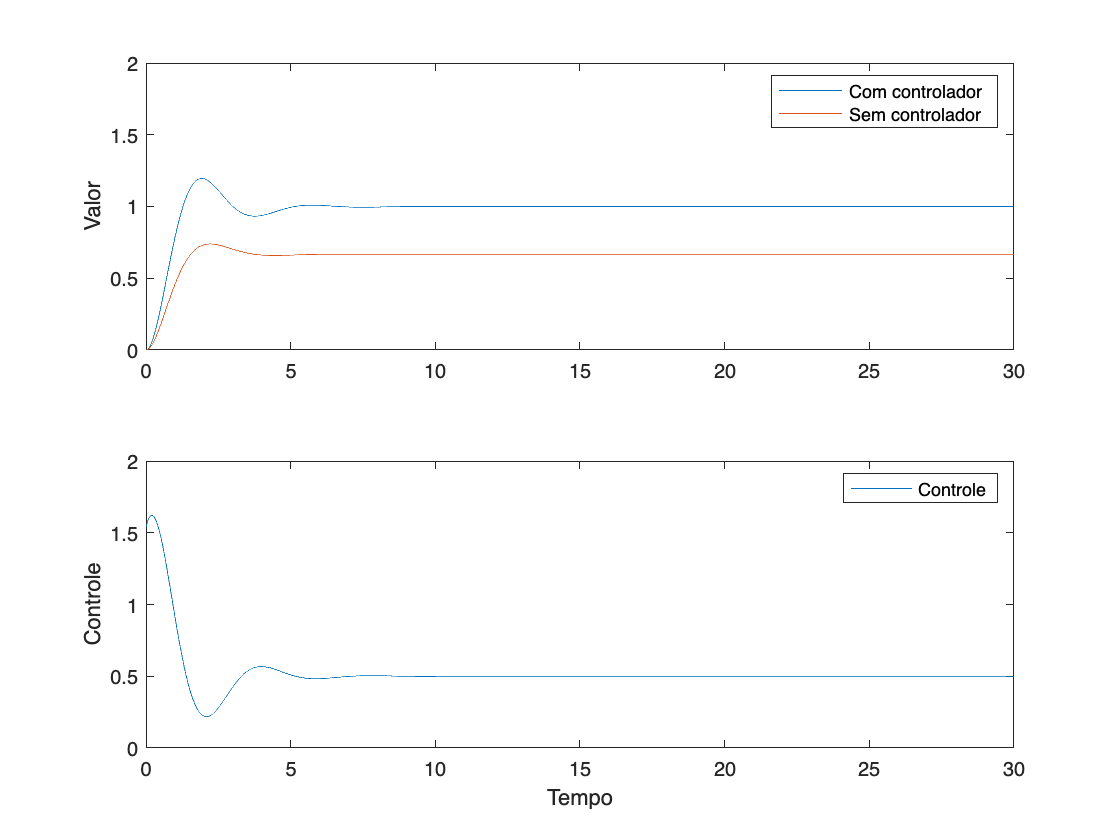

error_cont = sim_cont.Error(:,2);
time_cont = sim_cont.Error(:,1);
control_cont = sim_cont.ControlAction(:,2);
output_cont = sim_cont.Output(:,2);
model_cont = sim_cont.Output(:,3);

figure(2)

subplot(211);
plot(time_cont, output_cont); hold on;
plot(time_cont, model_cont); hold on;
ylim([0,2]);
legend("Com controlador", "Sem controlador");
ylabel("Valor");

subplot(212);
plot(time_cont, control_cont); hold on;
ylim([0,2]);
legend("Controle");
ylabel("Controle");
xlabel("Tempo");

IAE = 0;
ITAE = 0;

for i = 1:(20/cont_step_time)
    error_abs_ist = abs(error_cont(i));
    IAE = IAE + error_abs_ist;
    ITAE = ITAE + time_cont(i) * error_abs_ist;
end

IAE = IAE * cont_step_time

IAE = 1.0223

ITAE = ITAE * cont_step_time

ITAE = 1.1752

max_value = max(output_cont);
settling_value = output_cont(end);

overshoot = max_value - settling_value

overshoot = 0.1954

v10 = settling_value * 0.1;
v90 = settling_value * 0.9;
output_bigger_v10 = find(output_cont >= v10);
output_less_v90 = find(output_cont <= v90);
t10 = time_cont(output_bigger_v10(1));
t90 = time_cont(output_less_v90(end));
RT = t90 - t10

RT = 0.8500

# Frequência de Corte e Largura de Faixa 

G_s = C_s * H_s

G_s =
 
        0.5442 s^2 + 0.56 s + 1.714
  ---------------------------------------
  0.01343 s^4 + 1.027 s^3 + 2.013 s^2 + s
 
Continuous-time transfer function.



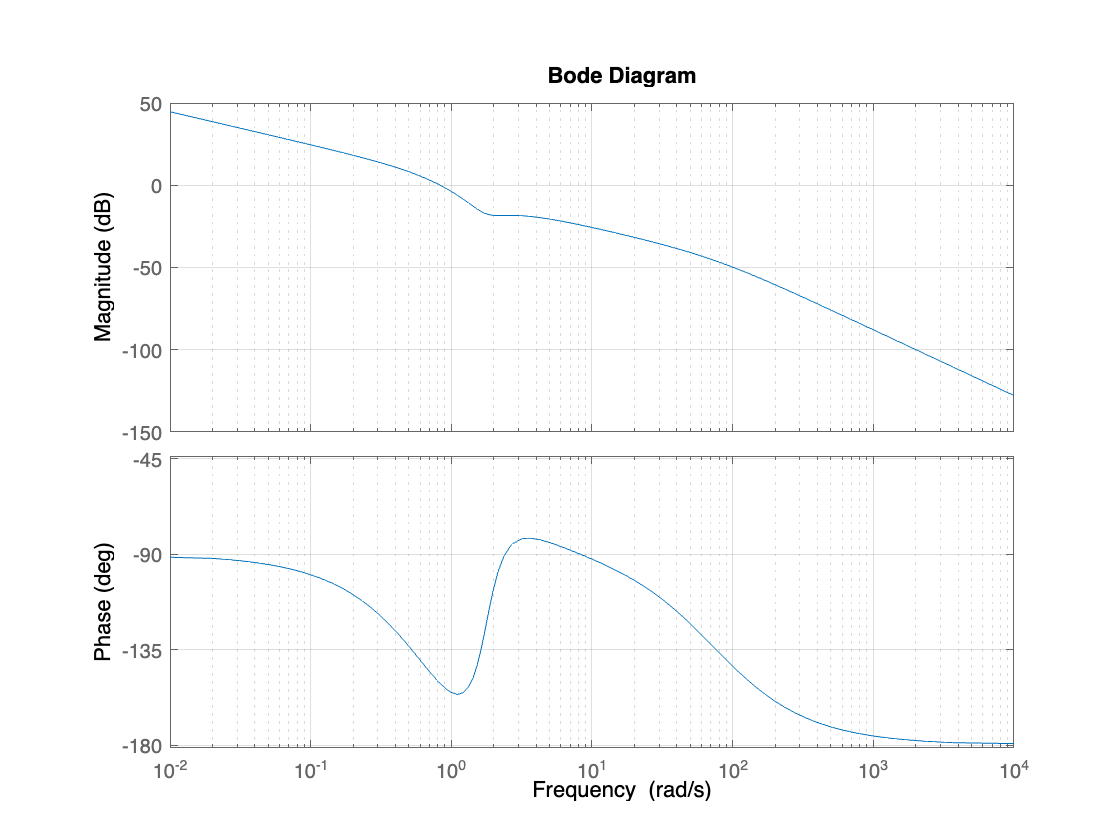

figure(3)
bode(G_s); grid on;

fc = 0.834

fc = 0.8340

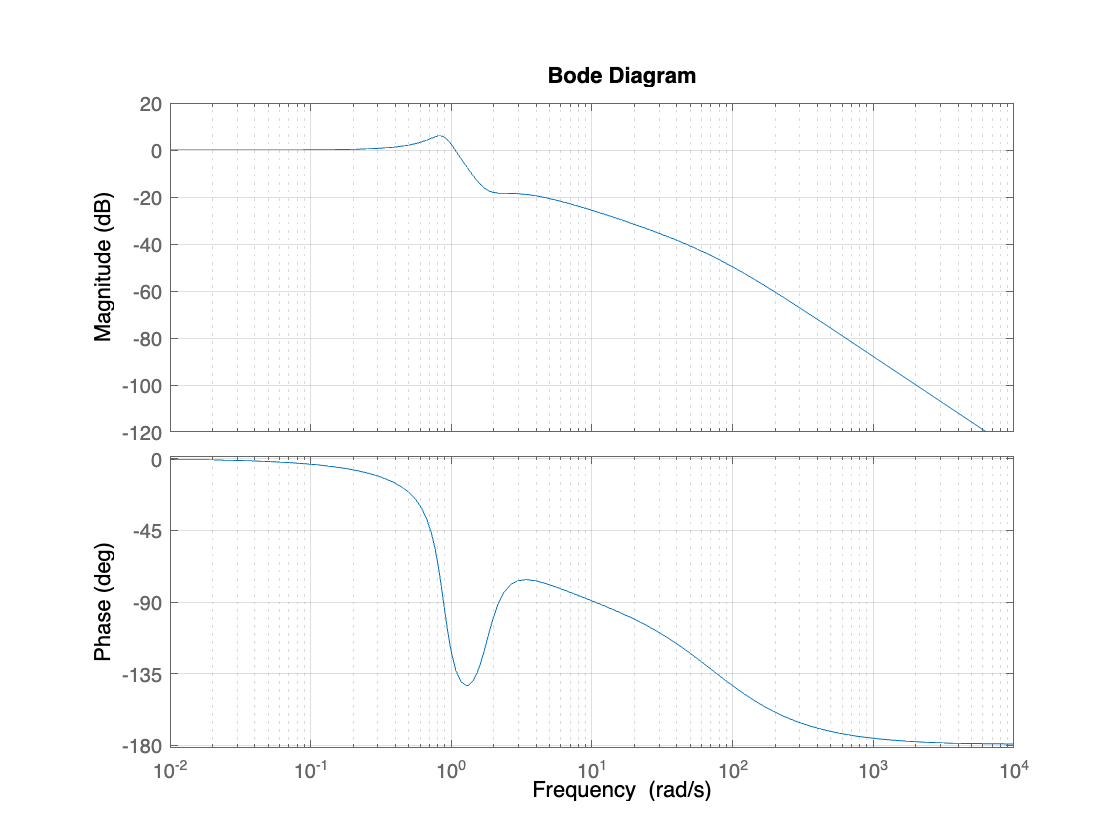

figure(4)
bode(feedback(G_s,1)); grid on;

Wbw = bandwidth(feedback(G_s,1))

Wbw = 1.1520

wa = Wbw * 40;
dt_max = 2*pi/wa

dt_max = 0.1364

delta_time = 0.075;

# Discretização

sf = tf([1, -1], delta_time,delta_time);
sb = tf([1,-1],[delta_time, 0 ],delta_time);
C_z = Kp + Ki/sf + Kd*sb/(Kd/20*sb+1)

C_z =
 
   0.03031 z^3 - 0.05157 z^2 + 0.02162 z
  ----------------------------------------
  0.006632 z^3 - 0.007639 z^2 + 0.001007 z
 
Sample time: 0.075 seconds
Discrete-time transfer function.



H_z = c2d(H_s,delta_time)

H_z =
 
  0.005352 z + 0.005091
  ----------------------
  z^2 - 1.855 z + 0.8607
 
Sample time: 0.075 seconds
Discrete-time transfer function.



# Simulação Discreta

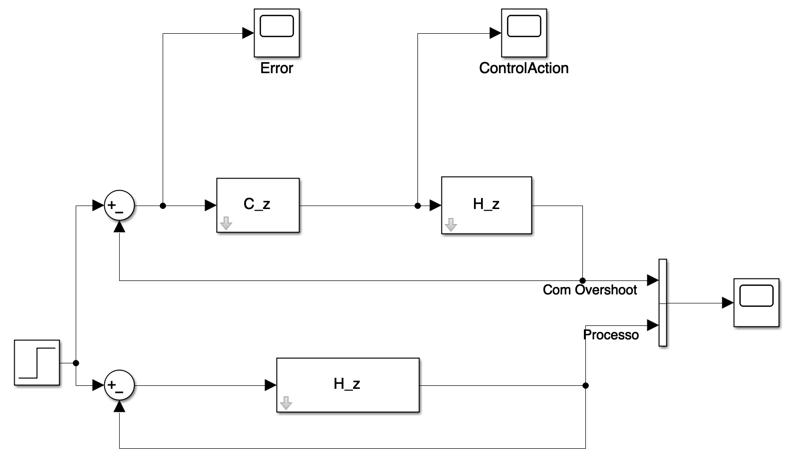

sim_disc = sim("disc.slx");

# Validação da Discretização

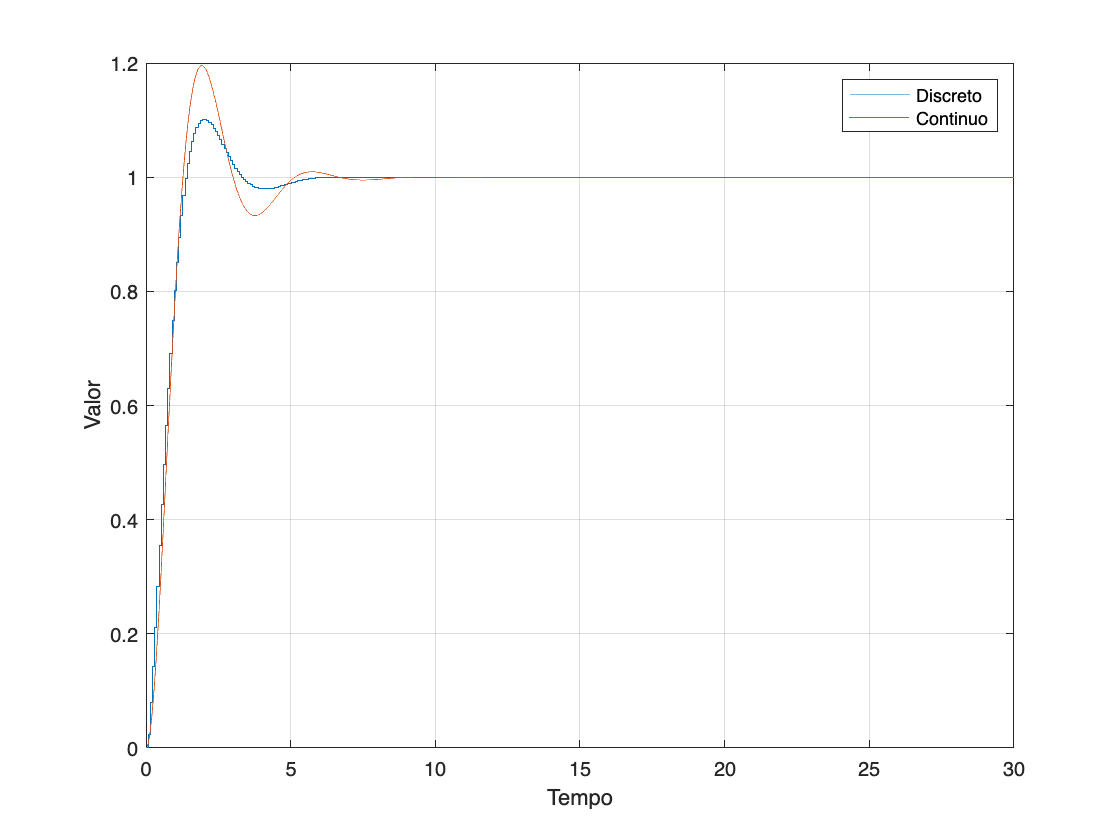

time_disc = sim_disc.Error(:,1);
output_disc = sim_disc.Output(:,2);
control_disc = sim_disc.ControlAction(:,2);

figure(5)

stairs(time_disc, output_disc); hold on;
plot(time_cont, output_cont); hold on;
grid on;
legend("Discreto", "Continuo")
xlabel("Tempo")
ylabel("Valor")

# Equação de Diferenças

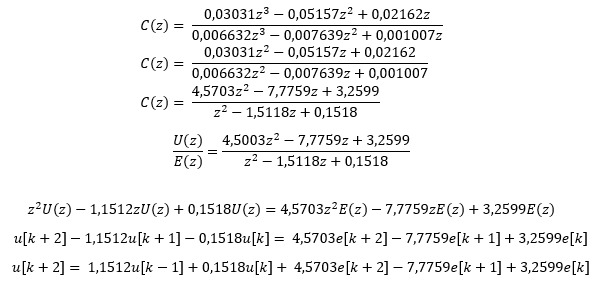

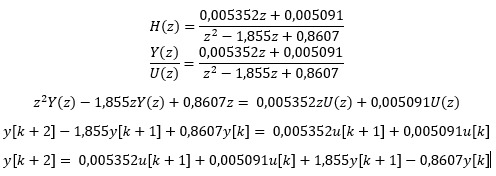

# Simulação por Equação de Diferenças

t = 0:delta_time:30;
w = ones(size(t));
[e, u, y] = discrete_simulation(delta_time, 30, w);

# Validação Equação de Diferenças

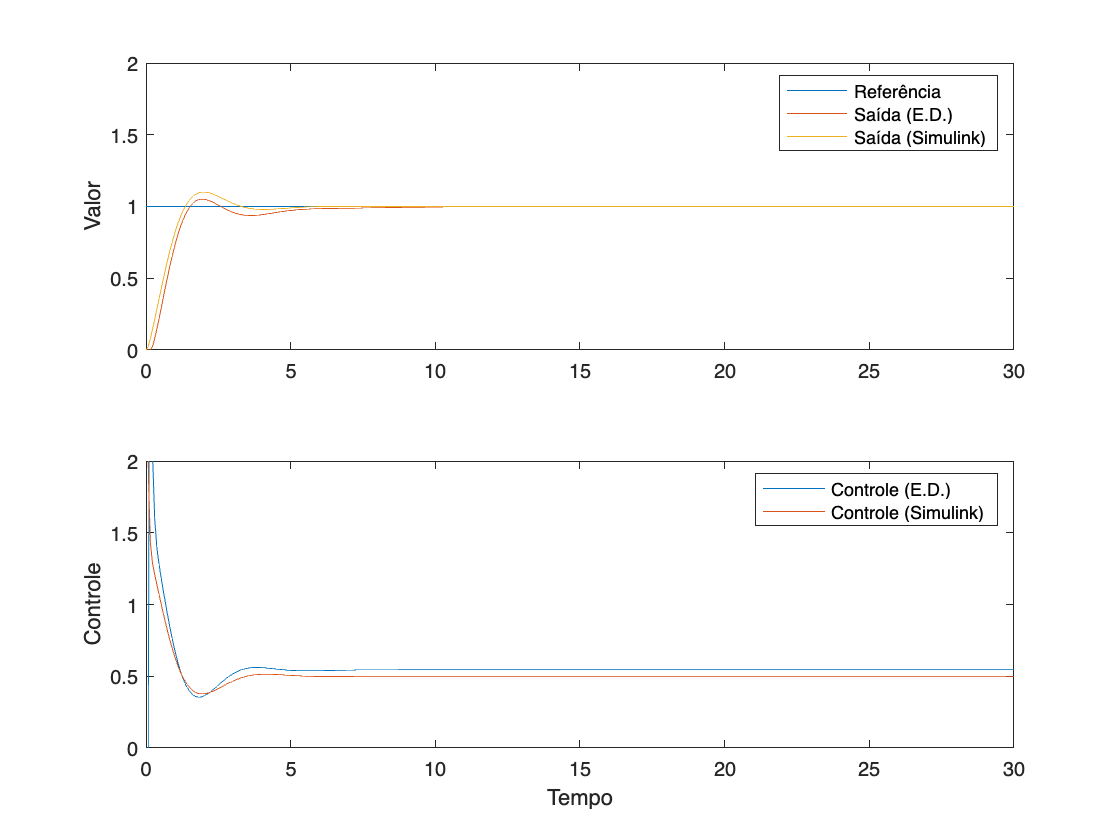

figure(6)

subplot(211);
plot(t, w); hold on;
plot(t, y); hold on;
plot(time_disc, output_disc); hold on;
ylim([0,2]);
legend("Referência", "Saída (E.D.)", "Saída (Simulink)");
ylabel("Valor");

subplot(212);
plot(t, u); hold on;
plot(time_disc, control_disc); hold on;
ylim([0,2]);
legend("Controle (E.D.)", "Controle (Simulink)");
ylabel("Controle");
xlabel("Tempo");